%Set Path to Python executable using "which python" in command prompt

pyenv("Version","/Path/to/Python/Executable")

ans =   PythonEnvironment with properties:

          Version: "3.9"
       Executable: "/Users/parrot/.virtualenvs/Oxford-AI/bin/python"
          Library: "/usr/local/Cellar/python@3.9/3.9.1_8/Frameworks/Python.framework/Versions/3.9/lib/libpython3.9.dylib"
             Home: "/Users/parrot/.virtualenvs/Oxford-AI"
           Status: NotLoaded
    ExecutionMode: InProcess


%Import audio features from specmatlab python script

py.importlib.import_module('specmatlab')

ans =   Python module with properties:

               pd: [1×1 py.module]
              ipd: [1×1 py.module]
         wav_name: [1×21 py.str]
              PCA: [1×1 py.abc.ABCMeta]
                i: 1.7345
                X: [1×1 py.pandas.core.frame.DataFrame]
           isfile: [1×1 py.function]
            color: [1×1 py.module]
      window_size: [1×1 py.int]
             math: [1×1 py.module]
            t_end: [1×1 py.pandas.core.series.Series]
        ref_table: [1×1 py.pandas.core.frame.DataFrame]
               np: [1×1 py.module]
                l: [1×1 py.list]
        file_path: [1×25 py.str]
           random: [1×1 py.module]
    sampling_rate: [1×1 py.int]
         hop_size: [1×1 py.int]
         num_rows: [1×1 py.int]
          mixture: [1×1 py.module]
          listdir: [1×1 py.builtin_function_or_method]
              sig: [1×1 py.module]
        soundfile: [1×1 py.module]
               os: [1×1 py.m

audiolist=cell(py.specmatlab.data)

audiolist = 1×6 cell array
    {1×161 py.list}    {1×5 py.list}    {1×2 py.list}    {1×9 py.list}    {1×1 py.list}    {1×1 py.list}


wav_ls=cell(py.specmatlab.wav_ls)

wav_ls = 1×6 cell array
    {1×21 py.str}    {1×21 py.str}    {1×21 py.str}    {1×21 py.str}    {1×21 py.str}    {1×21 py.str}


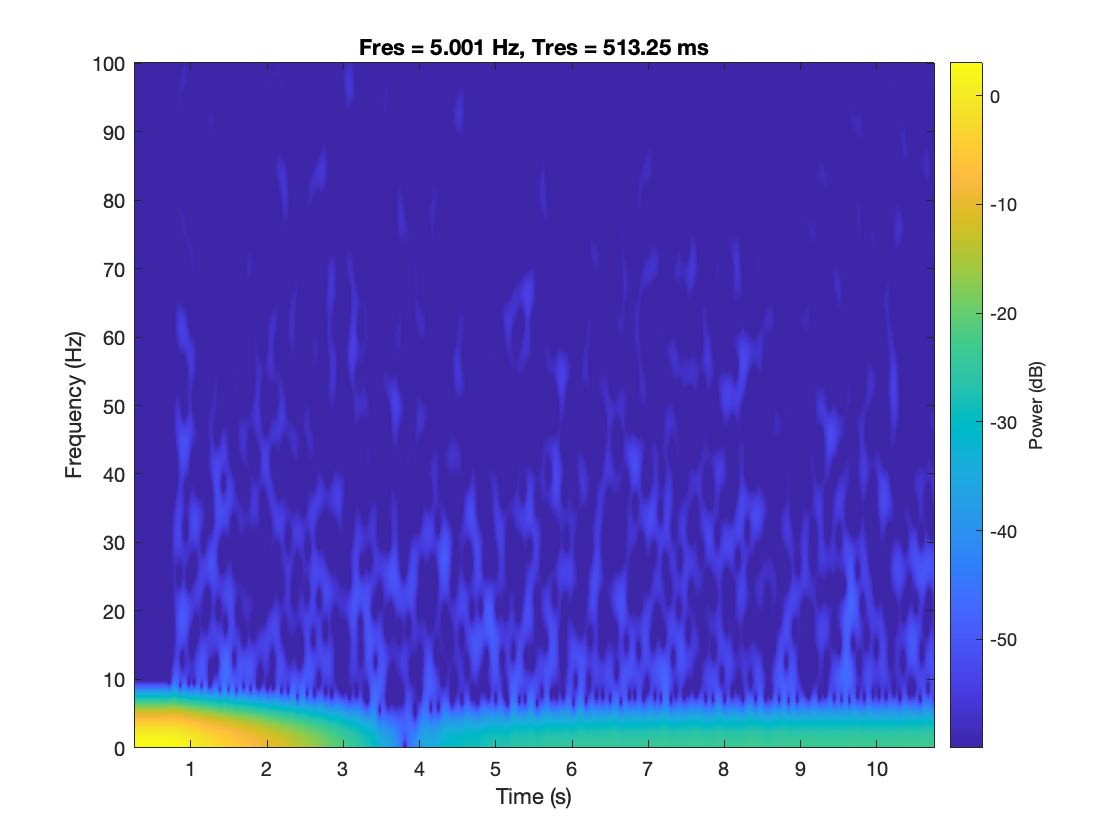

for i=1:length(audiolist)
    
    fs=double(py.specmatlab.sampling_rate);
    for j=1:length(audiolist{i})
        audio=audiolist{i}{j};
        audio=double(py.array.array('d',audio));
        
    
     pspectrum(audio,fs,'spectrogram',...
    'FrequencyLimits',[0 100],...
    'FrequencyResolution',5,...
    'OverlapPercent',99,'MinTHreshold',-60)
    
    %save spectrograms output to spec matlab folder
    
    newName = sprintf('%sfigure_%d.png',string(wav_ls{i}),j);
    newFile = fullfile('/Path/to/current/directory/spec matlab plots',newName);
    imwrite(getframe(gcf).cdata, newFile);
    end        
    
    
end 